testLoop = LoopMatrix(6)

testLoop =      0     6    12    18    24    30
     1     7    13    19    25    31
     2     8    14    20    26    32
     3     9    15    21    27    33
     4    10    16    22    28    34
     5    11    17    23    29    35


testReshape = ReshapeMatrix(6)

testReshape =      0     6    12    18    24    30
     1     7    13    19    25    31
     2     8    14    20    26    32
     3     9    15    21    27    33
     4    10    16    22    28    34
     5    11    17    23    29    35


testCompute = ComputationMatrix(6)

testCompute =      0     6    12    18    24    30
     1     7    13    19    25    31
     2     8    14    20    26    32
     3     9    15    21    27    33
     4    10    16    22    28    34
     5    11    17    23    29    35


% Generate 1000 random numbers distributed normally with standard deviation
% 2. randn will try to keep mean close to 0 because of normal distribution
e_i = 2 * randn(1000, 1);

mean_e_i = mean(e_i);
std_dev_e_i = std(e_i);

disp(['Mean of e_i: ', num2str(mean_e_i)]);

Mean of e_i: 0.041535


disp(['Standard deviation of e_i: ', num2str(std_dev_e_i)]);

Standard deviation of e_i: 1.9408


% Generate 1000 uniformly distributed random numbers in the interval (0, 10)
x_i = 10 * rand(1000, 1);
% Compute y_i = 2.4x_i + ε_i
y_i = 2.4*x_i + e_i;

% Plot the data points (x_i, y_i)
hold on
scatter(x_i, y_i, 'b.')
xlabel('x_i');
ylabel('y_i');
title('Scatter plot of (x_i, y_i)');
% Find the 10th largest number in y_i
sorted_y_i = sort(y_i, 'descend');
tenth_largest_y_i = sorted_y_i(10);

% Find the corresponding x_i for the 10th largest y_i
corresponding_xi_index = find(y_i == tenth_largest_y_i, 1);
corresponding_xi = x_i(corresponding_xi_index);

disp(['10th largest y_i: ', num2str(tenth_largest_y_i)]);

10th largest y_i: 25.0833


disp(['Corresponding x_i: ', num2str(corresponding_xi)]);

Corresponding x_i: 8.9894


% Use least squares to find the optimal Beta
Beta_hat = (x_i' * x_i) \ (x_i' * y_i);

disp('Computed value of Beta:');

Computed value of Beta:


disp(Beta_hat);

    2.4081



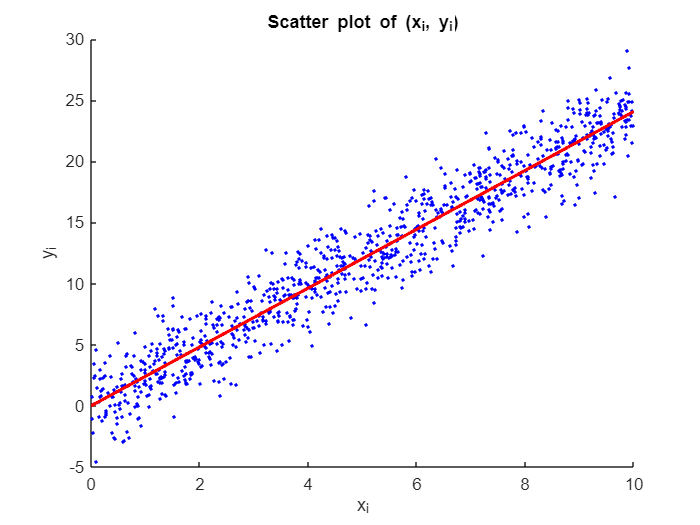

% Plot the fitted curve
x_fit = linspace(0, 10, 1000); % Generate x values for fitting curve
y_fit = Beta_hat * x_fit;

hold on
plot(x_fit, y_fit, 'r-', 'LineWidth', 2);
hold off

p1 = [-1, 0, 0, 0, 1];
poly2str(p1, 'x')

ans = '   -1 x^4 + 1'

roots_p1 = roots(p1)

roots_p1 =   -1.0000 + 0.0000i
   0.0000 + 1.0000i
   0.0000 - 1.0000i
   1.0000 + 0.0000i


factored_form_p1 = poly(roots_p1)

factored_form_p1 =     1.0000    0.0000   -0.0000    0.0000   -1.0000


p2 = [-6, 11, -6, 1];
poly2str(p2, 'x')

ans = '   -6 x^3 + 11 x^2 - 6 x + 1'

roots_p2 = roots(p2)

roots_p2 =     1.0000
    0.5000
    0.3333


factored_form_p2 = poly(roots_p2)

factored_form_p2 =     1.0000   -1.8333    1.0000   -0.1667


p3 = [1, 2.3, 2.3, 0.9, 1.7, 2.8, 1];
poly2str(p3, 'x')

ans = '   x^6 + 2.3 x^5 + 2.3 x^4 + 0.9 x^3 + 1.7 x^2 + 2.8 x + 1'

roots_p3 = roots(p3)

roots_p3 =    0.6000 + 0.8000i
   0.6000 - 0.8000i
  -1.0000 + 1.0000i
  -1.0000 - 1.0000i
  -1.0000 + 0.0000i
  -0.5000 + 0.0000i


factored_form_p3 = poly(roots_p3)

factored_form_p3 =     1.0000    2.3000    2.3000    0.9000    1.7000    2.8000    1.0000


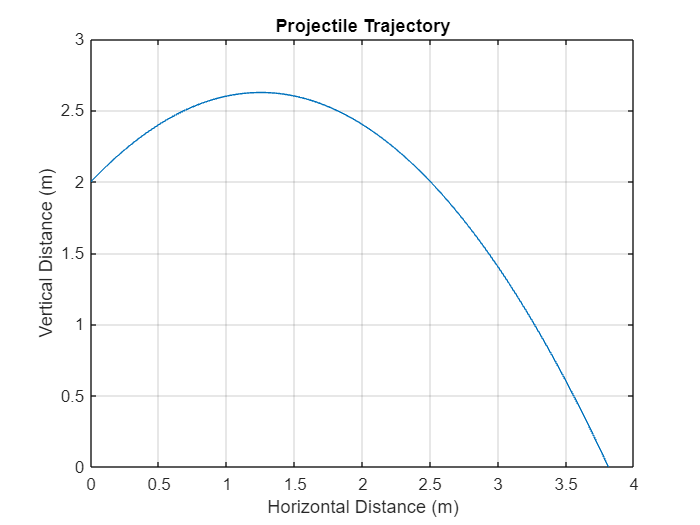

v = 5; % Initial velocity (m/s)
theta = 45; % Launch angle (degrees)
x0 = 0; % Initial horizontal position (m)
y0 = 2; % Initial vertical position (m)

draw_trajectory(v, theta, x0, y0);


% Given values
theta = 45; % Launch angle (degrees)
xt = 10; % Target's x-coordinate (m)
yt = 3.5; % Target's y-coordinate (m)
y0 = 2; % Initial vertical position (m)

% Calculate the required speed
v_required = find_required_speed(theta, xt, yt, y0);
disp(['The required speed to hit the target: ', num2str(v_required), ' m/s']);

The required speed to hit the target: 9.8869 m/s


% Given parameters
rs = [0.3, 1.8, 2.2, 2.5, 2.7];  % Growth rate parameters
x0 = 0.1; % Initial condition
num_iterations = 50; % Number of iterations

% Compute iterates for each value of r
for i = 1:length(rs)
    r = rs(i);
    x = logistic_map(r, x0, num_iterations);
    
    % Display the iterates
    disp(['r = ', num2str(r)]);
    disp(x);
end

r = 0.3


    0.1000    0.0270    0.0079    0.0023    0.0007    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



r = 1.8


    0.1000    0.1620    0.2444    0.3324    0.3994    0.4318    0.4416    0.4439    0.4443    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444    0.4444



r = 2.2


    0.1000    0.1980    0.3494    0.5001    0.5500    0.5445    0.5456    0.5454    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455    0.5455



r = 2.5


    0.1000    0.2250    0.4359    0.6147    0.5921    0.6038    0.5981    0.6010    0.5995    0.6002    0.5999    0.6001    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000



r = 2.7


    0.1000    0.2430    0.4967    0.6750    0.5923    0.6520    0.6126    0.6407    0.6215    0.6351    0.6257    0.6323    0.6277    0.6310    0.6287    0.6303    0.6292    0.6300    0.6294    0.6298    0.6295    0.6297    0.6296    0.6297    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296    0.6296

